## Problem 20

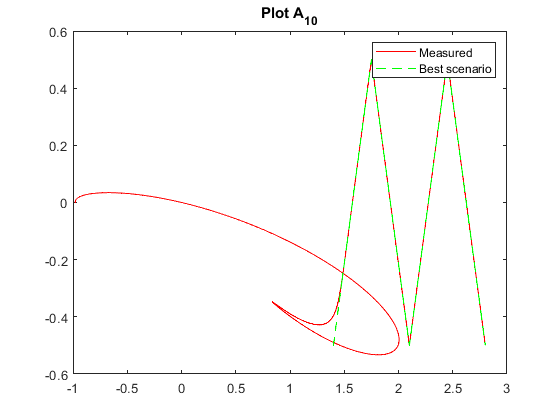

global GM m1 m2 m3 m4 L1 L2 dd2 L3 a4 I2 I3 I4 I1yy I2zz I3yy g n kT feff d1
addpath('C:\Users\Luky\Desktop\DTU\Robotics\Assignment\alto_robot_matlab')
omega = 15;
zeta = 1;
Jeff1=0.0198; % kgm^2
Jeff2=0.0242; % kgm^2
Jeff3=0.0027; % kgm^2
Jeff4=0.00038; % kgm^2
qr_1 = 0.35; % rad/s
qr_2 = 0.35; % rad/s
qr_3 = 0.35; % m
qr_4 = 0.35; % rad/s
kT = 0.17; % Nm/V
feff = 0.000024; % Nm/(rad/s)
g = 9.81; % m/s^2;
GM = [0.1165, -0.58249, 0.77665, 0, 0, -0.34302; -0.00629, 0.03143, -0.0419, 0, 0, 1.75696; 0.06163, -0.30815, 0.41087, 0, 0, 1.51275; 0.00629, -0.03143, 0.0419, 0, 0, 2.95543; -0.09601, 0.48004, -0.64005, 0, 0, 0.2783; -0.00444, 0.02218, -0.02957, 0, 0, 1.72344; 0.06288, -0.31439, 0.41918, 0, 0, 1.84144; 0.00444, -0.02218, 0.02957, 0, 0, 2.98895; 0.08157, -0.40787, 0.54383, 0, 0, -0.23374; -0.00328, 0.01638, -0.02184, 0, 0, 1.69978; 0.06363, -0.31813, 0.42418, 0, 0, 2.17679; 0.00328, -0.01638, 0.02184, 0, 0, 3.01261; -0.07088, 0.3544, -0.47253, 0, 0, 0.20132; -0.00251, 0.01255, -0.01673, 0, 0, 1.68231; 0.06411, -0.32054, 0.42739, 0, 0, 2.51613; 0.00251, -0.01255, 0.01673, 0, 0, 3.03008];
a4 = 1.02; % m
d1 = 1.5; % m
B=feff/kT;

KD1 = 9.3763;
KD2 = 10.1528;
KD3 = 6.35869;
KD4 = 5.94927;

Kp1 = 202.6765;
Kp2 = 208.5;
Kp3 = 180.0441;
Kp4 = 176.9735;

KI1 = 1323.5294;
KI2 = 1323.5294;
KI3 = 1323.5294;
KI4 = 1323.5294;

J1=Jeff1/kT;
J2=Jeff2/kT;
J3=Jeff3/kT;
J4=Jeff4/kT;

I1=0.18526;
I1yy=0.00392;
I2=1.98342;
I2zz=0.06534;
I3=1.12492;
I3yy=0.02646;
I4=0.17607;

L1=0.67;
L2=1.7;
L3=1.65;
a4=0.98;

m1=4.9;
m2=8.1;
m3=4.9;
m4=2.2;

dd2=0.64;
n = 53;
GM = [0.06563, -0.32813, 0.4375, 0, 0, 1.4; 0.1875, -0.9375, 1.25, 0, 0, -0.5; 0.06563, -0.32813, 0.4375, 0, 0, 1.75; -0.1875, 0.9375, -1.25, 0, 0, 0.5; 0.06563, -0.32813, 0.4375, 0, 0, 2.1; 0.1875, -0.9375, 1.25, 0, 0, -0.5; 0.06563, -0.32813, 0.4375, 0, 0, 2.45; -0.1875, 0.9375, -1.25, 0, 0, 0.5];


simulink = sim('problem20_21.mdl',8);   % start simulation
plot(p(:,1),p(:,2),'r'), hold on
plot(pr(:,1),pr(:,2),'g--')
legend('Measured','Best scenario');
hold off
title('Plot A_{10}')


%vis4link(M,1,18)

## Problem 21

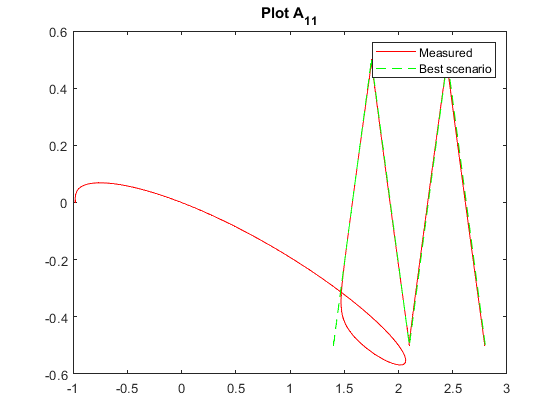

KD1 = 3.494;
KD2 = 4.2704;
KD3 = 0.4763;
KD4 = 0.0669;

Kp1 = 26.2059;
Kp2 = 32.0294;
Kp3 = 3.5735;
Kp4 = 0.5029;

KI1 = 0;
KI2 = 0;
KI3 = 0;
KI4 = 0;

simulink = sim('problem20_21.mdl',8);   % start simulation
plot(p(:,1),p(:,2),'r'), hold on
plot(pr(:,1),pr(:,2),'g--')
legend('Measured','Best scenario');
title('Plot A_{11}')